% TODO: По ДИ вторую производную с сетки оформить, а не с функции.

clc
close
clear

### **Практическая часть.**

Общие параметры.

TextSize = 20; % размер текста
roundnum = 4; % число знаков после запятой при округлении
N = 100; % количество узлов 

x_left = 0; % диапазон изменения x
x_right = 5; % вычисляем шаг по x (равномерный)
h = (x_right - x_left) / (N - 1); % шаг

x = x_left:h:x_right; % узлы
y = f_int_ot_x(x); % значение функции в узлах
x_c = x(1:N-1) + 0.5 * h; % середины элементарных отрезков

График функции.

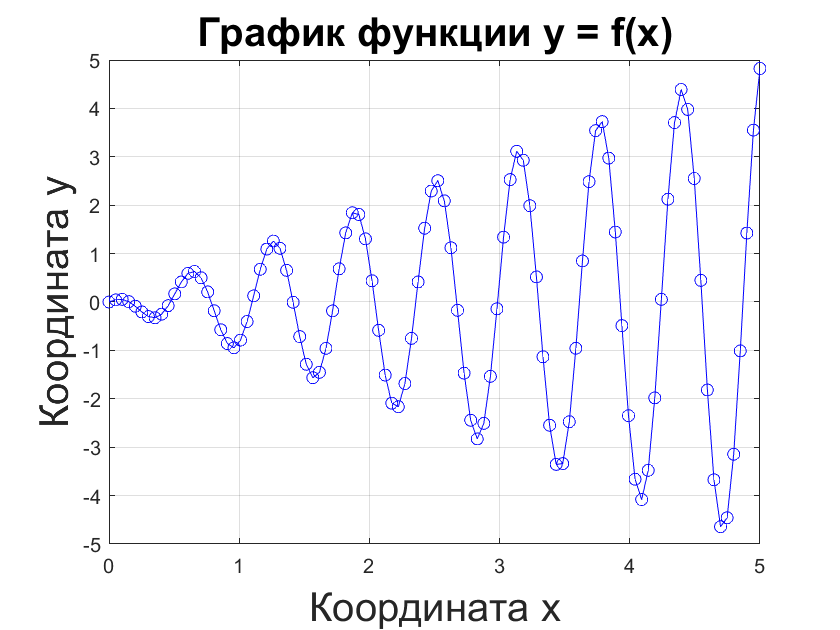

figure(1)
plot(x, y, '-bo')
grid on
title(['График функции y = f(x)'], 'FontSize', TextSize)
xlabel('Координата x', 'FontSize', TextSize)
ylabel('Координата y', 'FontSize', TextSize)

Метод левых прямоугольников.

I_left = sum(f_int_ot_x(x(1:N-1))) * h;

eps_left = max(d1_f(x)) * h / 2;

Метод правых прямоугольников.

I_right = sum(f_int_ot_x(x(2:N))) * h;

eps_right = max(d1_f(x)) * h / 2;

Метод центральных прямоугольников.

I_cent = sum(f_int_ot_x(x_c)) * h;

eps_cent = max(d2_f(x)) * h^2 / 24;

Метод трапеций.

I_trap = (f_int_ot_x(x_left) + f_int_ot_x(x_right) + ...
    2 * sum(f_int_ot_x(x(2:N-1)))) * h / 2;

eps_trap = max(d2_f(x)) * h^2 / 12;

Метод Симпсона.

I_Simp = (f_int_ot_x(x_left) + f_int_ot_x(x_right) + ...
    4 * sum(f_int_ot_x(x_c)) + 2 * sum(f_int_ot_x(x(2:N-1)))) * h / 6;

eps_Simp = max(d4_f(x)) * h^4 / 2880;

Вычисляем производную разностью вправо.

k = 50;

% dydx_1_right = (y(k+1) - y(k)) / (x(k+1) - x(k));
% dydx_exac1 = d1_f(x(k));

dydx_1_right = (f_int_ot_x(x(k)+h) - f_int_ot_x(x(k))) / h;
dydx_exac1 = d1_f(x(k));

eps_dydx1 = abs((dydx_1_right - dydx_exac1) / dydx_exac1) * 100;

Вывод результатов.

disp(['Метод левых прямоугольников:        ', num2str(roundn(I_left, -roundnum)), ', погрешность: ', num2str(roundn(eps_left, -roundnum))])

Метод левых прямоугольников:        -0.2506, погрешность: 1.1922


disp(['Метод правых прямоугольников:       ', num2str(roundn(I_right, -roundnum)), ', погрешность: ', num2str(roundn(eps_right, -roundnum))])

Метод правых прямоугольников:       -0.0069, погрешность: 1.1922


disp(['Метод центральных прямоугольников:  ', num2str(roundn(I_cent, -roundnum)), ', погрешность: ', num2str(roundn(eps_cent, -roundnum))])

Метод центральных прямоугольников:  -0.1329, погрешность: 0.049


disp(['Метод трапеций:                     ', num2str(roundn(I_trap, -roundnum)), ', погрешность: ', num2str(roundn(eps_trap, -roundnum))])

Метод трапеций:                     -0.1287, погрешность: 0.098


disp(['Метод Симпсона:                     ', num2str(roundn(I_Simp, -roundnum)), ', погрешность: ', num2str(roundn(eps_Simp, -roundnum))])

Метод Симпсона:                     -0.1315, погрешность: 0.0001


disp(['Производная в узле k = ', num2str(k), ' с первым порядком аппроксимации: ', num2str(roundn(dydx_1_right, -roundnum)), ', ', newline, ...
    'ошибка: ', num2str(roundn(eps_dydx1, -roundnum)), '%'])

Производная в узле k = 50 с первым порядком аппроксимации: 4.2335, 
ошибка: 58.6044%


### **Исследовательская часть.**

Вычисление производной со вторым порядком аппроксимации в точке x0.

x0 = 2.4;

dydx_2_right = (f_int_ot_x(x0+h) - f_int_ot_x(x0-h)) / (2 * h); % finite different unstructed mash (grid)
dydx_exac2 = d1_f(x0);


% dydx_2_right = (((2 * x(k) * (x(k) - x(k+1)) + x(k+1)^2 + (x(k+1)^2 - x(k)^2)) * y(k-1)) + ...
%     ((2 * x(k) * (x(k+1) - x(k-1)) + (x(k-1)^2 - x(k+1)^2)) * y(k)) + ...
%     ((2 * x(k) * (x(k-1) - x(k)) + (x(k)^2 - x(k-1)^2)) * y(k+1))) / ...
%     ((x(k) - x(k+1)) * x(k-1)^2 + (x(k+1) - x(k-1)) * x(k)^2 + (x(k-1) - x(k)) * x(k+1)^2);
% dydx_exac2 = d1_f(x(k));
% 
% eps_dydx2 = abs((dydx_2_right - dydx_exac2) / dydx_exac2) * 100
eps_dydx2 = abs((dydx_2_right - dydx_exac2) / dydx_exac2) * 100;

Вычисление интеграла с помощью библиотечных функций Matlab. Сравнение результатов с методов прямоугольников.

syms x_int;
f = x_int * cos(10*x_int);

matlab_int1 = vpa(int(f, x_int, [x_left, x_right]));
matlab_int2 = vpaintegral(f, x_int, [x_left, x_right]);

eps_matlab1 = abs((matlab_int1 - I_cent) / I_cent) * 100;
eps_matlab2 = abs((matlab_int2 - I_cent) / I_cent) * 100;

Вывод результатов.

disp(['Результат MATLAB с использованием "int": ', num2str(roundn(double(matlab_int1), -roundnum)), ', погрешность ', newline, ...
    'в сравнении с методом центральных прямоугольников: ', num2str(roundn(double(eps_matlab1), -roundnum))])

Результат MATLAB с использованием "int": -0.1315, погрешность 
в сравнении с методом центральных прямоугольников: 1.0538


disp(['Результат MATLAB с использованием "varintegral": ', num2str(roundn(double(matlab_int2), -roundnum)), ', погрешность ', newline, ...
    'в сравнении с методом центральных прямоугольников: ', num2str(roundn(double(eps_matlab2), -roundnum))])

Результат MATLAB с использованием "varintegral": -0.1315, погрешность 
в сравнении с методом центральных прямоугольников: 1.0538


disp(['Производная в узле x0 = ', num2str(x0), ' со вторым порядком аппроксимации: ', num2str(roundn(dydx_2_right, -roundnum)), ', ', newline, ...
    'ошибка: ', num2str(roundn(eps_dydx2, -roundnum)), '%'])

Производная в узле x0 = 2.4 со вторым порядком аппроксимации: 21.1928, 
ошибка: 4.356%
